# Classify human electrocardiogram (ECG) Signals

Given is the following ECG signal

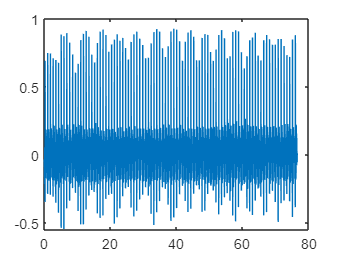

clear all
close all
% load ecg signal 
ecg =load('ecg.mat');
% Graphical Output
% Time Signal
t = [0:length(ecg.data)-1]/ecg.fs;
plot(t,ecg.data)

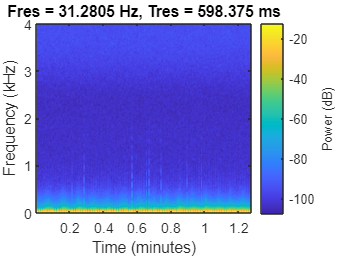

% Short Time Fourier Analysis -- Spectrogram
pspectrum(ecg.data,ecg.fs,'spectrogram')

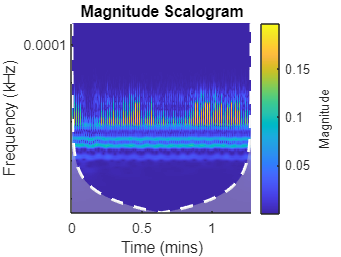

% Wavelet Analysis -- Scalogram
cwt(ecg.data,[],ecg.fs)

In general people can be divided in three groups:

- persons with cardiac arrhythmia (ARR)

- persons with congestive heart failure (CHF), and

- persons with normal sinus rhythms (NSR). 

The goal of this PStA is to classify human electrocardiogram (ECG) signals using the Short Time Fourier Transformation and the Continuous Wavelet Transform (CWT) and deep convolutional neural networks (CNNs). The resulting CNNs shall be used to classify the given ECG signal to ARR, CHF, and NSR, respectively. 

### Matlab Example

The Matlab Example [Classify Time Series Using Wavelet Analysis and Deep Learning - MATLAB & Simulink Example - MathWorks Deutschland](https://de.mathworks.com/help/releases/R2020b/wavelet/ug/classify-time-series-using-wavelet-analysis-and-deep-learning.html) can be taken as a basis. It uses ECG data (the training and test data are publicly available from [PhysioNet](https://physionet.org/)) obtained from three groups of people: persons with cardiac arrhythmia (ARR), persons with congestive heart failure (CHF), and persons with normal sinus rhythms (NSR). In total  162 ECG recordings from three PhysioNet databases are used: [MIT-BIH Arrhythmia Database](https://www.physionet.org/physiobank/database/mitdb/) , [MIT-BIH Normal Sinus Rhythm Database](https://www.physionet.org/physiobank/database/nsrdb/) , and [The BIDMC Congestive Heart Failure Database](https://www.physionet.org/physiobank/database/chfdb/); more specifically, 96 recordings from persons with arrhythmia, 30 recordings from persons with congestive heart failure, and 36 recordings from persons with normal sinus rhythms. Two deep CNNs, GoogLeNet and SqueezeNet, pretrained for image recognition, are adapted to classify ECG waveforms based on a time-frequency representation -- the Wavelet Transformation.

## Tasks

- Complete the Live Script

- Dokument and explain your code with theoretical background -- detailed and understandable -- within the Live Script. Use additional plottings.

- Dokumentation and transparent coding has an important impact on the mark!

- Use the following time-frequency representations and investigate the impact on the ECG classification: Short Time Fourier Transformation and Wavelet Transformation

- Use the following pretrained deep CNNs and compare the results for the ECG classification; GoogLeNet, SqueezeNet and AlexNet.

## Data Preprocessing & Datastore

Generate the time-frequency representation using

- Short Time Fourier Transformation and

- Wavelet Transformation

and generate the corresponding data stores.

Compare the impact on the CNNs by comparing the confusion charts!

### **I. First step is to download the ECG training and test data from PhysioNet GitHub Repository and use it to produce the time frequency representation to train our network.**

Create the directory and path to the data.

clear('tempdir')
setenv('tmp','C:\Users\shaif\Desktop\THR\WS 22\DSP\') %Path of Directory
tempdir

ans = 'C:\Users\shaif\Desktop\THR\WS 22\DSP\'

### **II. Unzip the downloaded data and Load the data file into the MATLAB workspace. **

This folder contains:

- `ECGData.mat`

- `Modified_physionet_data.txt`

- `License.txt`

- `README.md `

`ECGData.mat` holds the data used in this project. The text file, `Modified_physionet_data.txt`, is required by PhysioNet's copying policy and provides the source attributions for the data as well as a description of the preprocessing steps applied to each ECG recording.

% unzip(fullfile(tempdir,'physionet_ECG_data-main.zip'),tempdir)
load(fullfile(tempdir,'ECGData.mat'))

Error using load
Unable to find file or directory 'C:\Users\shaif\Desktop\THR\WS 22\DSP\ECGData.mat'.

### **III. Store the preprocessed data of each category**

To store the preprocessed data of each category, first create ECG data directories `dataDir1 and dataDir2` inside `tempdir`. We rename the dataDir1 as '**Scalograms**' and dataDir2 as '**Spectrograms**' for our convenience to execute Continuous Wavelet Transformation and Short-Time Fourier Transformation. Then create three subdirectories in both Scalograms and Spectrograms named after each ECG category. The helper function `helperCreateECGDirectories` does this. `helperCreateECGDirectories` accepts `ECGData`, the name of an ECG data directory, and the name of a parent directory as input arguments.

parentDir1 = tempdir;
dataDir1 = 'Scalograms';

helperCreateECGDirectories(ECGData,parentDir1,dataDir1);

Unrecognized function or variable 'ECGData'.

parentDir2 = tempdir;
dataDir2 = 'Spectograms';

helperCreateECGDirectories(ECGData,parentDir2,dataDir2);

** Plot a representative of each ECG category**

The helper function `helperPlotReps` is used for this purpose, as it accepts `ECGData` as input.

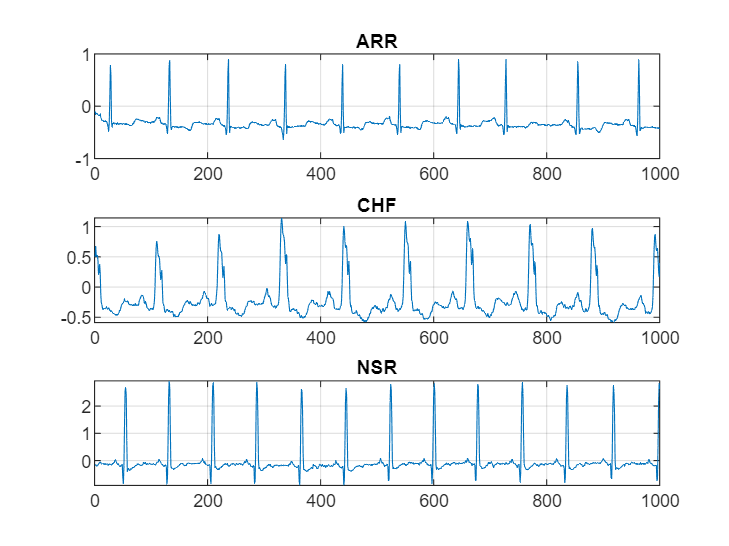

helperPlotReps(ECGData)

# 1. Continuous Wavelet Transformation (CWT)

### **1.1 Create Time-Frequency Representations**

The Time-Frequency representations are called scalograms. A scalogram is the absolute value of the CWT coefficients of a signal. To create the scalograms, precompute a CWT filter bank. Precomputing the CWT filter bank is the preferred method when obtaining the CWT of many signals using the same parameters.

Create a CWT filter bank using `cwtfilterbank` for a signal with 1000 samples. Use the filter bank to take the CWT of the first 1000 samples of the signal and obtain the scalogram from the coefficients.

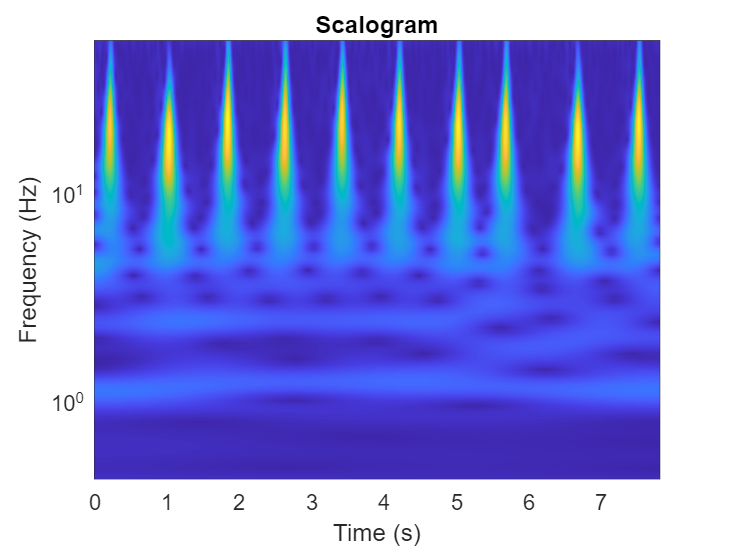

Fs = 128;
fb = cwtfilterbank('SignalLength',1000,...
    'SamplingFrequency',Fs,...
    'VoicesPerOctave',12);
sig = ECGData.Data(1,1:1000);
[cfs,frq] = wt(fb,sig);
t = (0:999)/Fs;figure;pcolor(t,frq,abs(cfs))
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)')

### **1.2 Create the scalograms as RGB images  **

To be compatible with the pre-trained Networks architecture, we create the scalograms as RGB images using the helper function `helperCreateRGBfromTF`. Each RGB image is an array with the dimensions 224x224x3. 

helperCreateRGBfromTF(ECGData,parentDir1,dataDir1)

### **1.3 Divide Scalograms Images into Training and Validation Data**

Load the scalogram images as an image datastore. The `imageDatastore` function automatically labels the images based on folder names and stores the data as an ImageDatastore object.

allImages1 = imageDatastore(fullfile(parentDir1,dataDir1),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

Randomly we divided the images into two groups, one for training and the other for validation. 

Set 80% of the images for training and the rest for validation. For the purpose of reproducibility, we set the random seed to the default value.

rng default
[imgsTrain1,imgsValidation1] = splitEachLabel(allImages1,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain1.Files))]);

Number of training images: 130


disp(['Number of validation images: ',num2str(numel(imgsValidation1.Files))]);

Number of validation images: 32


### **1.4 Development of Convolutional Neural Network (CNN) Models**

For this purpose, the following pretrained networks shall be used: GoogLeNet, SqueezeNet and AlexNet. The results of obtained from each model have been compared and tested.

#### (1.4.1) GoogLeNet

 Load the pretrained GoogLeNet neural network by installing the network package `googlenet`.

net1 = googlenet;

(a) Extract and display the layer graph from the network.

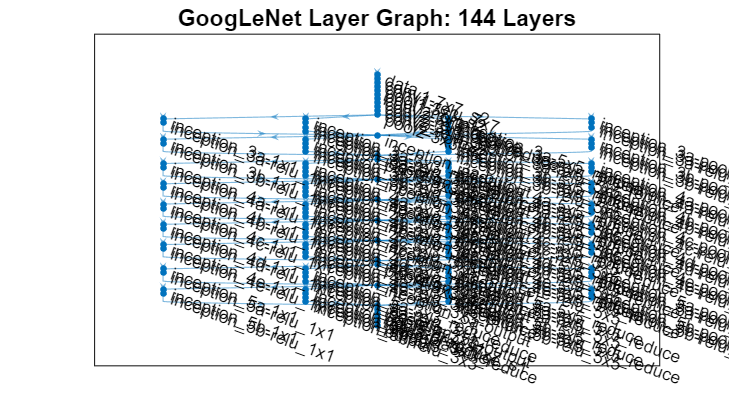

lgraphGN = layerGraph(net1);
numberOfLayers = numel(lgraphGN.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraphGN)
title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);

(b) Inspect the first element of the network Layers property in order to ensure that the images of size 224 x 224 x 3 have created.

net1.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


(c) Modify GoogLeNet Network Parameters

To prevent overfitting, a dropout layer is used. A dropout layer randomly sets input elements to zero with a given probability.

Set the dropout probability to 0.6 in the final dropout layer `'``pool5-drop_7x7_s1``'.`

newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraphGN = replaceLayer(lgraphGN,'pool5-drop_7x7_s1',newDropoutLayer);

The convolutional layers of the network extract image features that the last learnable layer and final classification layer use to classify the input image. These two layers, `'``loss3-classifier``'` and `'``output``'` in GoogLeNet, contain information on how to combine the features that the network extracts into class probabilities, a loss value, and predicted labels.

To retrain GoogLeNet to classify the RGB images, replace the fully connected layer '`loss3-classifier'` with a new fully connected layer adapted to the data with the number of filters equal to the number of classes.

To learn faster in the new layers than in the transferred layers, increase the learning rate factors of the fully connected layer.

numClasses = numel(categories(imgsTrain1.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraphGN = replaceLayer(lgraphGN,'loss3-classifier',newConnectedLayer);

The classification layer specifies the output classes of the network. We replace the classification layer with a new one without class labels. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraphGN = replaceLayer(lgraphGN,'output',newClassLayer);

#### (1.4.2) SqueezeNet 

Load the pretrained SqueezeNet neural network by downloading and installing the Network package.

net2 = squeezenet;

(a) Extract the layer graph from the network.

lgraphSqz = layerGraph(net2);
disp(['Number of Layers: ',num2str(numel(lgraphSqz.Layers))])

Number of Layers: 68


(b) Confirm that SqueezeNet is configured for images of size 227x227x3.

disp(lgraphSqz.Layers(1).InputSize)

   227   227     3



(c) Modify SqueezeNet Network Parameters

To retrain SqueezeNet for our requirements, we modify the Network parameters similar to that of the GoogLeNet.

Inspect the last six network layers.

lgraphSqz.Layers(end-5:end)

ans =   6×1 Layer array with layers:

     1   'drop9'                             Dropout                      50% dropout
     2   'conv10'                            Convolution                  1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'                       ReLU                         ReLU
     4   'pool10'                            2-D Global Average Pooling   2-D global average pooling
     5   'prob'                              Softmax                      softmax
     6   'ClassificationLayer_predictions'   Classification Output        crossentropyex with 'tench' and 999 other classes

To adjust the default probability for our requirement, we replace the `'``drop9``'` layer, the last dropout layer in the network, with a dropout layer of probability 0.6.

tmpLayer = lgraphSqz.Layers(end-5);
newDropoutLayer = dropoutLayer(0.6,'Name','new_dropout');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newDropoutLayer);

The last learnable layer in SqueezeNet is a 1-by-1 convolutional layer, `'``conv10``'`, and not a fully connected layer .Therefore we replace the `'``conv10``'` layer with a new convolutional layer adapted to the data, with the number of filters equal to the number of classes.

We set the Learn Rate Factor to 10, to learn faster in the new layers.

numClasses = numel(categories(imgsTrain1.Labels));
tmpLayer = lgraphSqz.Layers(end-4);
newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newLearnableLayer);

Replace the classification layer with a new one without class labels.

tmpLayer = lgraphSqz.Layers(end);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newClassLayer);

Confirm the dropout, connected, and output layers have been changed, by inspecting the last six layers of the network.

lgraphSqz.Layers(63:68)

ans =   6×1 Layer array with layers:

     1   'new_dropout'       Dropout                      60% dropout
     2   'new_conv'          Convolution                  3 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'       ReLU                         ReLU
     4   'pool10'            2-D Global Average Pooling   2-D global average pooling
     5   'prob'              Softmax                      softmax
     6   'new_classoutput'   Classification Output        crossentropyex

(d) Prepare RGB Data for SqueezeNet

For the purpose of creating augmented image datastores that accordingly resize the existing RGB images for the SqueezeNet architecture.

augimgsTrain1 = augmentedImageDatastore([227 227],imgsTrain1);
augimgsValidation1 = augmentedImageDatastore([227 227],imgsValidation1);


#### (1.4.3) AlexNet

Load the pretrained AlexNet neural network by downloading and installing the Network package.

net3 = alexnet;

(a) Extracting and displaying the layer graph from the network.

layersTransfer = net3.Layers; %preserving all layers 
lgraphAlx = layerGraph(layersTransfer);
disp(['Number of Layers: ',num2str(numel(lgraphAlx.Layers))])

Number of Layers: 25


(b) Confirm that AlexNet is configured for images of size 227x227x3.

disp(lgraphAlx.Layers(1).InputSize)

   227   227     3



(c) Modify AlexNet Network Parameters

To retrain AlexNet for our requirements, we modify the Network parameters similar to that of the GoogLeNet and SqueezeNet.

Inspect the last six network layers.

lgraphAlx.Layers()

ans =   25×1 Layer array with layers:

     1   'data'     Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0  0

To adjust the default probability for our requirement, we replace the `'``drop7``'` layer, the last dropout layer in the network, with a dropout layer of probability 0.6.

tmpLayer = lgraphAlx.Layers(22);
newDropoutLayer = dropoutLayer(0.6,'Name','New_dropout');
lgraphAlx = replaceLayer(lgraphAlx,tmpLayer.Name,newDropoutLayer);

Replace the fully connected layer `'``fc8``'` with a new fully connected layer with the number of filters equal to the number of classes. 

numClasses = numel(categories(imgsTrain1.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraphAlx = replaceLayer(lgraphAlx,'fc8',newConnectedLayer);

The classification layer specifies the output classes of the network. We replace the classification layer with a new one without class labels. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraphAlx = replaceLayer(lgraphAlx,'output',newClassLayer);

Confirm the dropout, connected, and output layers have been changed, by inspecting the last four layers of the network.

lgraphAlx.Layers(end-3:end)

ans =   4×1 Layer array with layers:

     1   'New_dropout'       Dropout                 60% dropout
     2   'new_fc'            Fully Connected         3 fully connected layer
     3   'prob'              Softmax                 softmax
     4   'new_classoutput'   Classification Output   crossentropyex

(d) Prepare RGB Data for AlexNet

For the purpose of creating augmented image datastores that accordingly resize the existing RGB images for the AlexNet architecture.

augimgsTrain1 = augmentedImageDatastore([227 227],imgsTrain1);
augimgsValidation1 = augmentedImageDatastore([227 227],imgsValidation1);

### 1.5 Training the Networks

Training a neural network is an iterative process that involves finding out the global minima of loss function. For that purpose, a gradient descent algorithm is used. We train our three networks in this step.

#### (1.5.1) GoogLeNet

**(a) Decide on the training parameters and train the network**

Training can be optimized by implementing hyperparametertuning process, which mainly focuses on achieving greater results on prediction by tuning some parameters. `InitialLearnRate` specifies the initial step size in the direction of the negative gradient of the loss function. `MiniBatchSize` defines how large of a subset of the training set to use in each iteration. One epoch is a full pass of the training algorithm over the entire training set. `MaxEpochs` describes the maximum number of epochs to be used for training. 

Using trial and error method, we find the best value for the number of epochs and batch-size to generate a good model without overfitting and underfitting. We found the optimum `MaxEpochs` value to be 10 and `MiniBatchSize` to be 11. We set the `InitialLearnRate` to 0.0001.

Training progress is visualized by setting `Plots` to `training-progress`.

For the purpose of reproducibility, we set the random number generator to the default value.

ilr_gn = 0.0001; %Initial learning rate
miniBatchSize_gn = 11;
maxEpochs_gn = 10;

options1 = trainingOptions('sgdm',...
    'MiniBatchSize',miniBatchSize_gn,...
    'MaxEpochs',maxEpochs_gn,...
    'InitialLearnRate',ilr_gn,...
    'ValidationData',imgsValidation1,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Train the Network

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |       27.27% |       46.88% |       2.0721 |       1.2213 |      1.0000e-04 |
|       1 |          10 |       00:00:31 |       27.27% |       68.75% |       1.4475 |       0.8736 |      1.0000e-04 |
|       2 |          20 |       00:00:55 |       54.55% |       78.12% |       1.1657 |       0.5720 |      1.0000e-04 |
|       3 |          30 |       00:01:17 |       72.73% |       68.75% |       0.6993 |       0.5487 |      1.0000

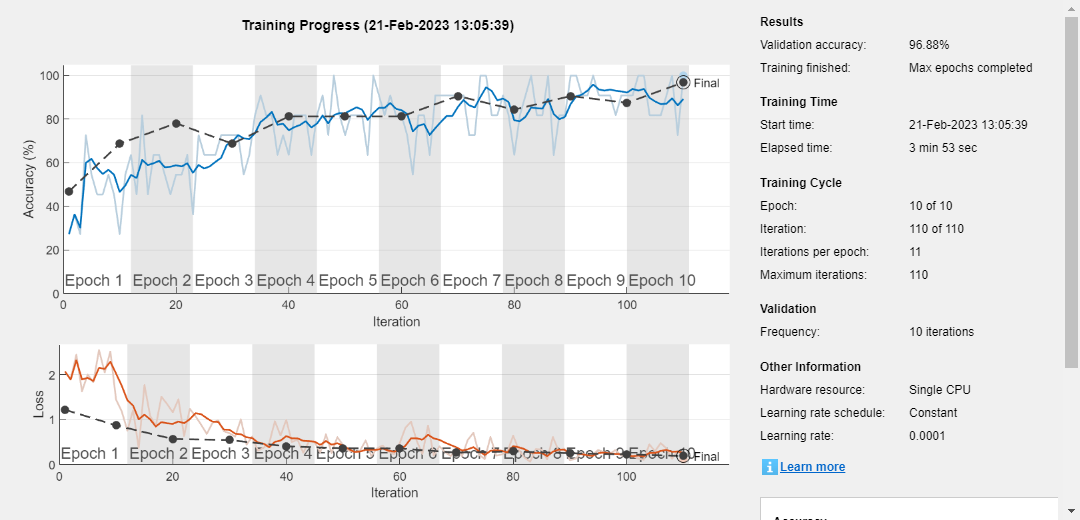

trainedGN = trainNetwork(imgsTrain1,lgraphGN,options1);

trainedGN.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


**(b) Evaluating the training results**

**GoogLeNet Accuracy**

Evaluate the network using the validation data. 

Since there is an insufficient amount of data to divide into training, validation, and testing, we treat the computed validation accuracy as the network accuracy.

[YPred1,~] = classify(trainedGN,imgsValidation1);
accuracy = mean(YPred1==imgsValidation1.Labels);
disp(['GoogLeNet Accuracy: ',num2str(100*accuracy),'%'])

GoogLeNet Accuracy: 96.875%


Display four sample validation images with their predicted labels.

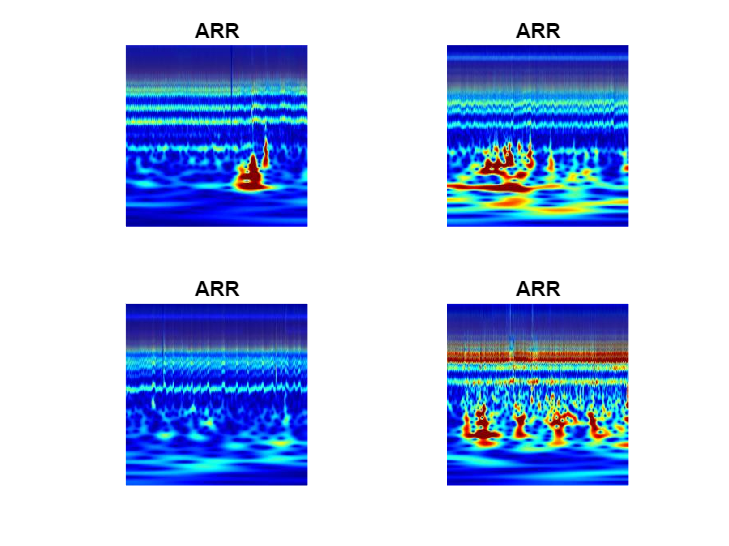

%idx = randperm(numel(imgsValidation.Files),4);
idx = [11,12,13,9];
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsValidation1,idx(i));
    imshow(I)
    label = YPred1(idx(i));
    title(string(label));
end

#### **(1.5.2) SqueezeNet**

**(a) Decide on the training parameters and train the network**

Using trial and error method, we find the best value for the number of epochs and batch-size to generate a good model without overfitting and underfitting. We found the optimum `MaxEpochs` value to be 17 and `MiniBatchSize` to be 10. Set the `InitialLearnRate` to 0.0001.

ilr_sn = 0.0001; %Initial learning rate
miniBatchSize_sn = 10;
maxEpochs_sn = 17;
valFreq = floor(numel(augimgsTrain1.Files)/miniBatchSize_sn);

valFreq = 13


options2 = trainingOptions('sgdm',...
    'MiniBatchSize',miniBatchSize_sn,...
    'MaxEpochs',maxEpochs_sn,...
    'InitialLearnRate',ilr_sn,...
    'ValidationData',augimgsValidation1,...
    'ValidationFrequency',valFreq,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

rng default

Training the network

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |       20.00% |       43.75% |       4.2032 |       1.8346 |      1.0000e-04 |
|       1 |          13 |       00:00:20 |       50.00% |       50.00% |       1.1404 |       1.0595 |      1.0000e-04 |
|       2 |          26 |       00:00:33 |       70.00% |       68.75% |       0.6700 |       0.7890 |      1.0000e-04 |
|       3 |          39 |       00:00:45 |       80.00% |       81.25% |       0.6308 |       0.7256 |      1.0000

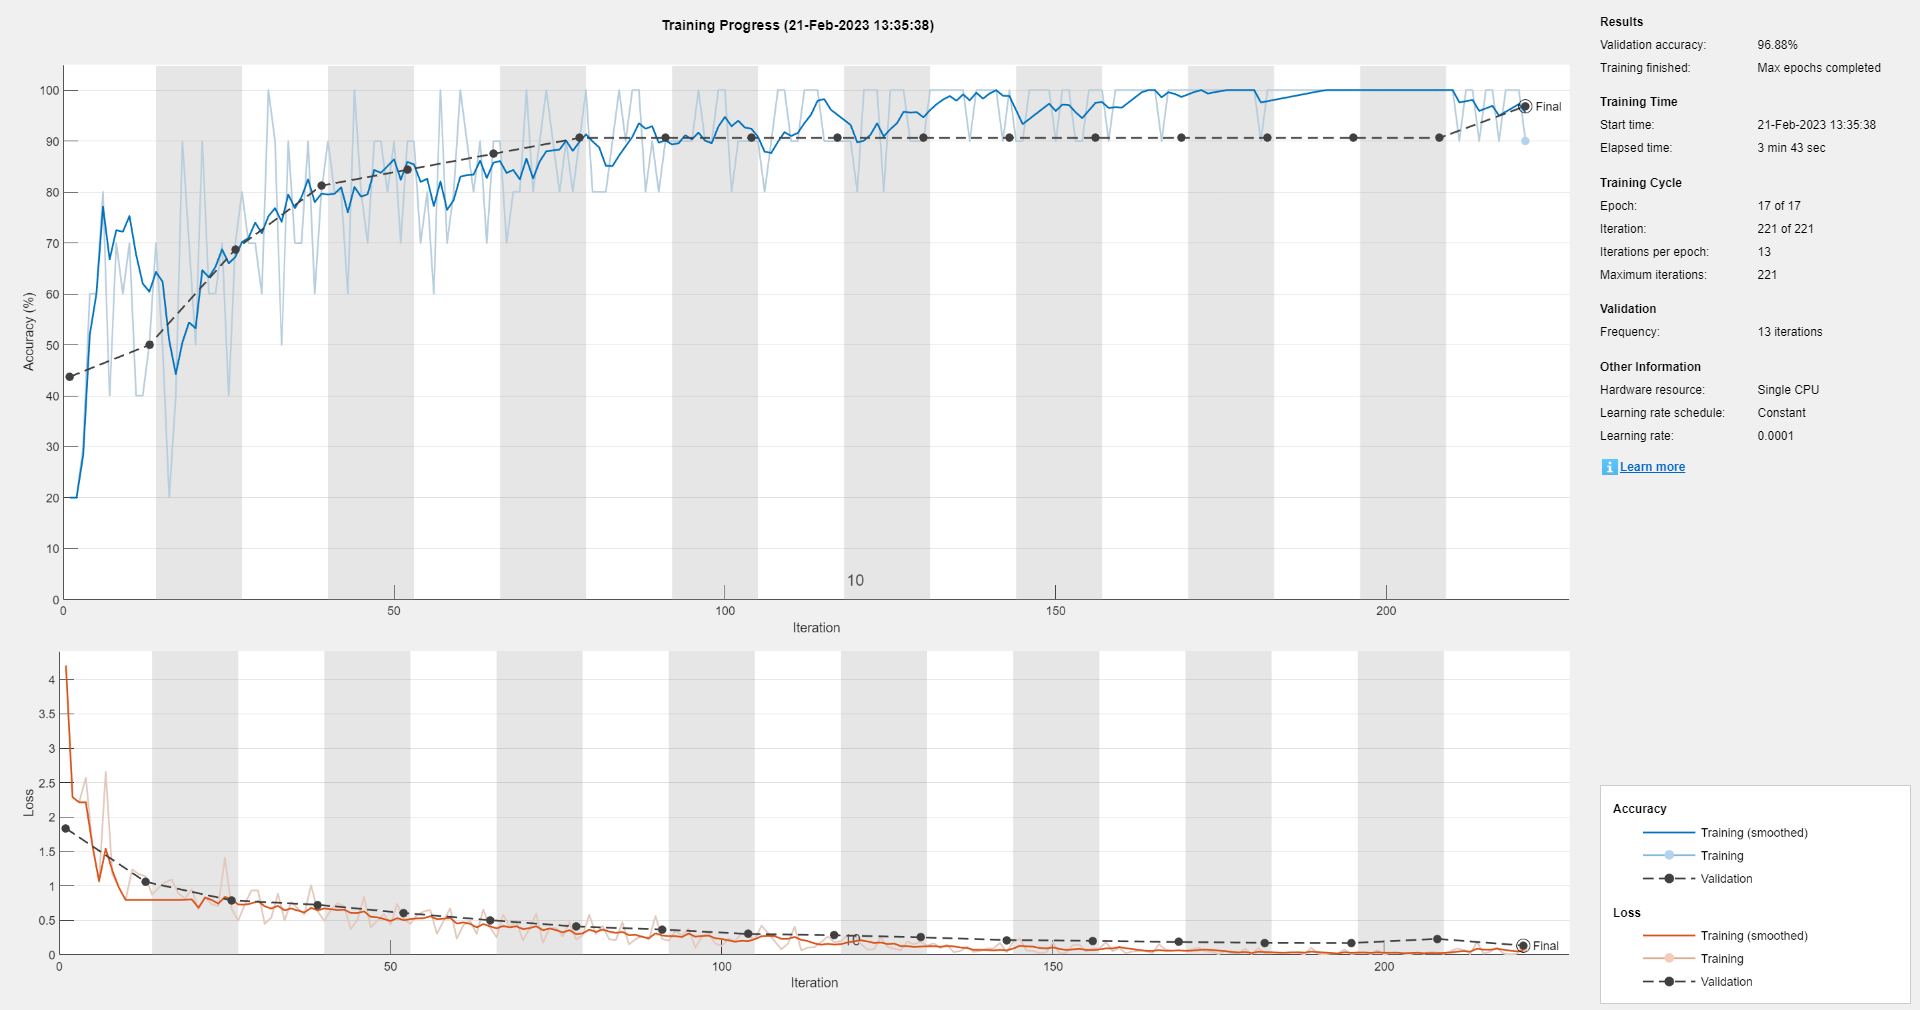

trainedSN = trainNetwork(augimgsTrain1,lgraphSqz,options2);

trainedSN.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


**(b) Evaluating the training results**

**SqueezeNet Accuracy**

Evaluate the network using the validation data.

[YPred2,~] = classify(trainedSN,augimgsValidation1);
accuracy = mean(YPred2==imgsValidation1.Labels);
disp(['SqueezeNet Accuracy: ',num2str(100*accuracy),'%'])

SqueezeNet Accuracy: 96.875%


Display four sample validation images with their predicted labels.

idx = [11,12,13,9];
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsValidation1,idx(i));
    imshow(I)
    label = YPred2(idx(i));
    title(string(label));
end

#### (1.5.3) AlexNet

**(a) Decide on the training parameters and train the network**

Using trial and error method, we find the best value for the number of epochs and batch-size to generate a good model without overfitting and underfitting.  We found the optimum `MaxEpochs` value to be 7 and `MiniBatchSize` to be 15. We set the `InitialLearnRate` to 0.0001.

ilr_an = 0.0001; %Initial learning rate
miniBatchSize_an = 15;
maxEpochs_an = 7;
valFreq = floor(numel(augimgsTrain1.Files)/miniBatchSize_an);

options3 = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize_an, ...
    'MaxEpochs',maxEpochs_an, ...
    'InitialLearnRate',ilr_an, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimgsValidation1, ...
    'ValidationFrequency',valFreq, ...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Training the Network

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       33.33% |       40.62% |       2.9515 |       1.4170 |      1.0000e-04 |
|       1 |           8 |       00:00:14 |       46.67% |       65.62% |       1.9882 |       0.6476 |      1.0000e-04 |
|       2 |          16 |       00:00:23 |       66.67% |       84.38% |       0.8421 |       0.4020 |      1.0000e-04 |
|       3 |          24 |       00:00:33 |       93.33% |       87.50% |       0.1398 |       0.3008 |      1.0000

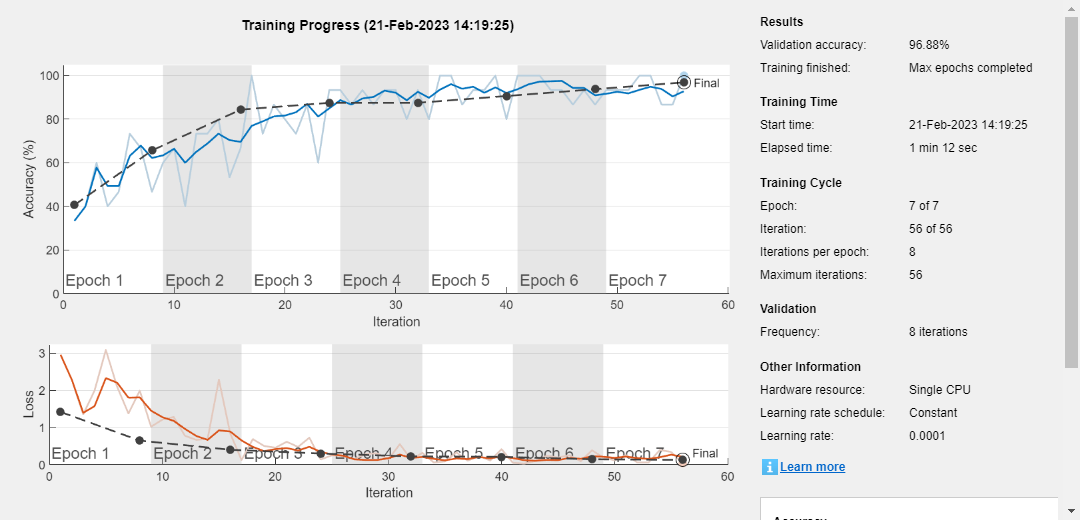

netTransfer1 = trainNetwork(augimgsTrain1,lgraphAlx,options3);

netTransfer1.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


**(b) Evaluating the training results**

**AlexNet Accuracy**

Evaluate the network using the validation data.

[YPred3,~] = classify(netTransfer1,augimgsValidation1);
accuracy = mean(YPred3==imgsValidation1.Labels);
disp(['ALexNet Accuracy: ',num2str(100*accuracy),'%'])

ALexNet Accuracy: 96.875%


Display four sample validation images with their predicted labels

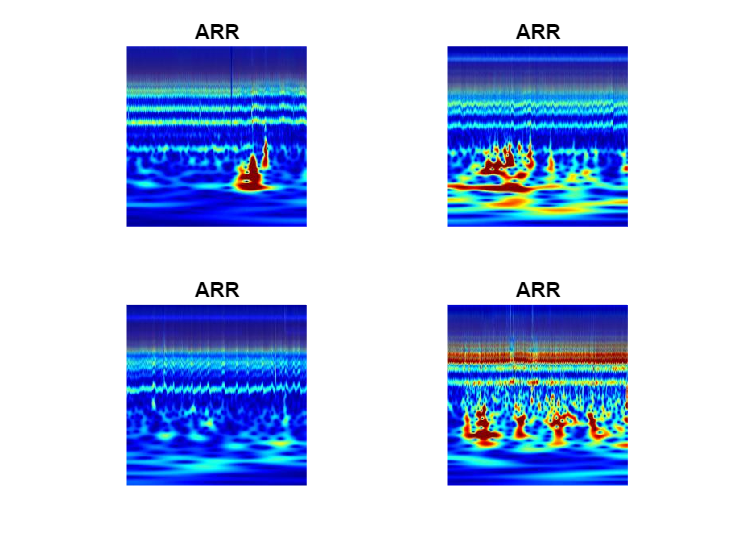

idx = [11,12,13,9];
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsValidation1,idx(i));
    imshow(I)
    label = YPred3(idx(i));
    title(string(label));
end

### 1.6 Testing and validating the Networks - Confusion Charts

We compare the results and the reliabilty of the different Time and Frequency Representations of the three different Networks.

#### Confusion Charts - Comparison

**(1.6.1) GoogleNet Confusion Chart**

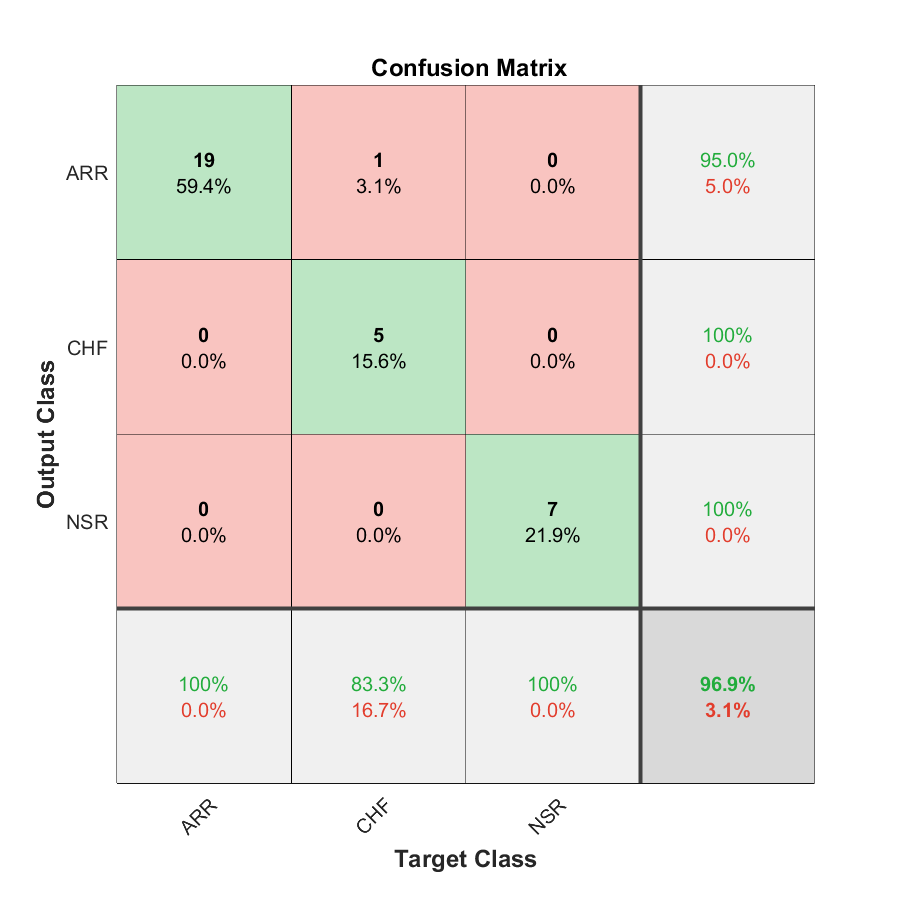

plotconfusion(imgsValidation1.Labels,YPred1)

The confusion matrix shows the relation between the output class and the target class regarding classification and misclassifications. For example, in CHF, we see that out of 6 testing images, 5 images were accurately classified, 1 image was misclassified as ARR. On the other hand, both all ARR and NSR images have got accurate predictions out of 19 and 7 images respectively.

**(1.6.2) SqueezNet Confusion Chart**

plotconfusion(imgsValidation1.Labels,YPred2)

Upon diagnosing the confusion chart obtained for SqueezeNet model, we can see that for both ARR and NSR images, out of 19 and 7 testing samples respectively, all are correctly classified. However, for CHF 5 images were classified correctly and 1 image was misclassified under ARR.

**(1.6.3) AlexNet Confusion Chart**

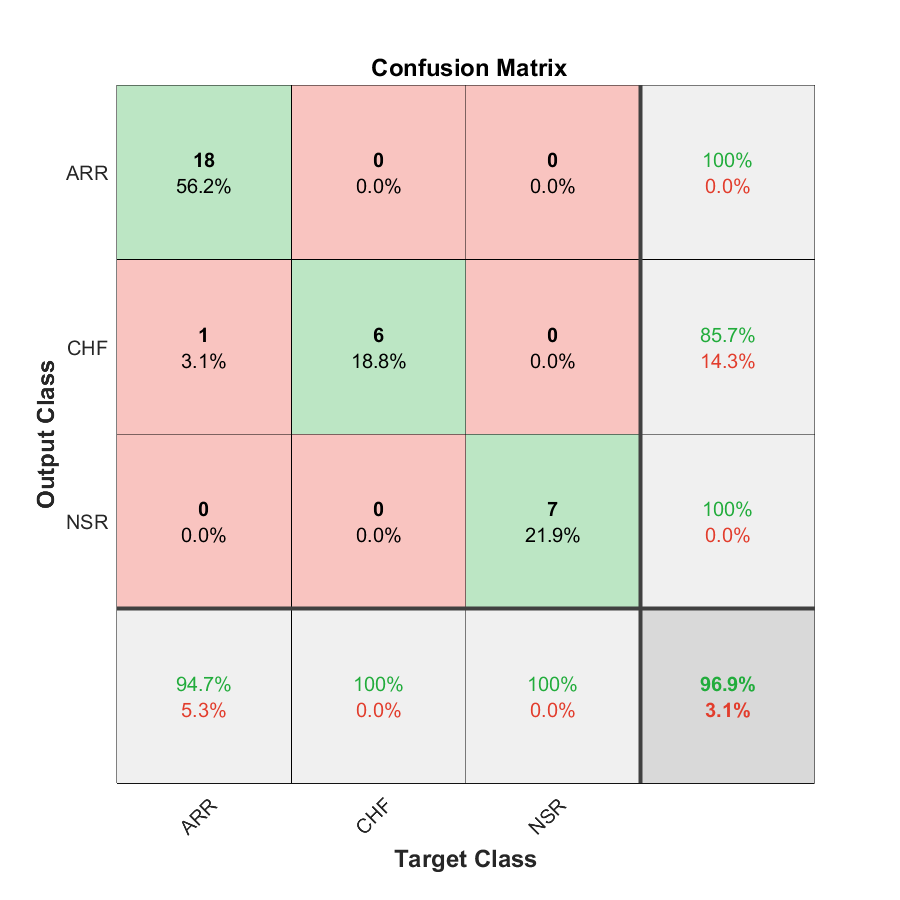

plotconfusion(imgsValidation1.Labels,YPred3)

While analysing the confusion chart obtained for AlexNet model, we can see that in ARR, out of 19 testing images, 18 images are correctly classified, meanwhile one image is misclassified as CHF. In contrast, all images have identified correctly for CHF and NSR out of 6 and 7 images respectively. 

### 1.7 Application of the Networks to the given ECG Signal

First step is to transform the given signal wavelet to an RGB Image:

ecg=load('ecg.mat');
parentDir = tempdir 

parentDir = 'C:\Users\abhir\Dropbox\My PC (LAPTOP-HNUHSA8N)\Desktop\DSP\'

dataDir = 'data'

dataDir = 'data'

data = ecg.data;

Unrecognized field name "data".


folderpath = strcat('given_signal');

cfs1 = abs(cwt(ecg.data,[],ecg.fs))

im = ind2rgb(im2uint8(rescale(cfs1)),jet(128));
imwrite(imresize(im,[224 224]),fullfile(folderpath,'Givensignal-WavletTransform.jpg'));

**Reading the given signal wavelet (Scalogram) image**

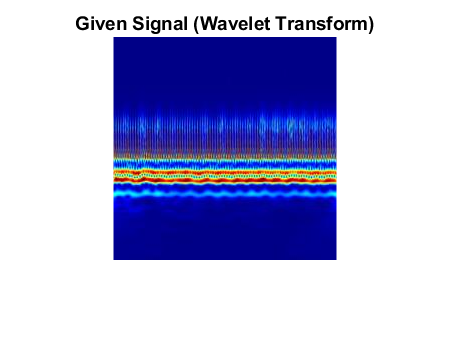

I = imread('C:\Users\abhir\Dropbox\My PC (LAPTOP-HNUHSA8N)\Desktop\DSP\given_signal\Givensignal-WavletTransform.jpg');
figure
imshow(I)
title('Given Signal (Wavelet Transform)')

#### (1.7.1) Prediction using GoogleNet

First we need to check the Image size because the GoogleNet model requires the image size to be the same as the input size of the network. If not, we need to resize the transformed image to the input image size of the GoogLeNet Network.

sizeGN = net1.Layers(1).InputSize; %Input image size of the GoogLeNet Network
Image_size = size(I); %Size of the given image
sizeGN

sizeGN =    224   224     3


Image_size

Image_size =    224   224     3


Prediction of the given signal by using GoogleNet Network.

labelGN2 = classify(trainedGN,I)

labelGN2 = categorical
     NSR 


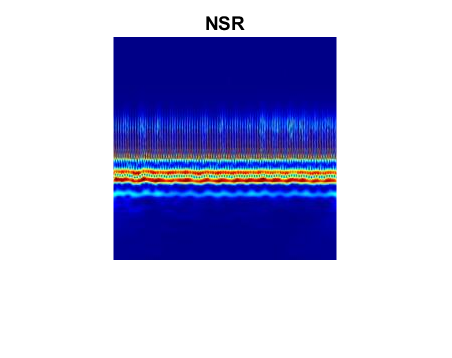

figure
imshow(I)
title(labelGN2)

#### (1.7.2) Prediction using SqueezeNet

Resizing the given transformed image to the input size of the SqueezeNet network.

sizeSQ = net2.Layers(1).InputSize; %Input image size of the SqueezeNet Network
I2 = imresize(I,sizeSQ(1:2));
Image_size2 = size(I2); %Size of the given image
sizeSQ

sizeSQ =    227   227     3


Image_size2

Image_size2 =    227   227     3


Prediction of the given signal by using SqueezeNet Network.

labelSQ2= classify(trainedSN,I2)

labelSQ2 = categorical
     NSR 


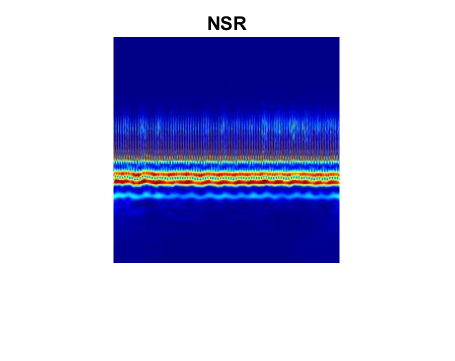

figure
imshow(I2)
title(labelSQ2)

#### (1.7.3) Prediction using AlexNet

Resize the given image to the input size of the AlexNet network.

sizeAN = net3.Layers(1).InputSize; %Input image size of the AlexNet Network
I3 = imresize(I,sizeAN(1:2));
Image_size3 = size(I3); %Size of the given image
sizeAN

sizeAN =    227   227     3


Image_size3

Image_size3 =    227   227     3


Prediction of the given signal by using AlexNet Network.

labelAL= classify(netTransfer1,I3)

labelAL = categorical
     ARR 


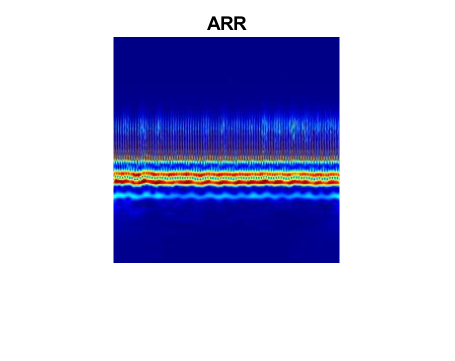

figure
imshow(I3)
title(labelAL)

# 2. Short Time Fourier Transformation (STFT)

The STFT is an enhanced mathematical methodology, derived from the discrete Fourier transform (DFT), to explore the instantaneous frequency as well as the instantaneous amplitude of localized waves with timevarying characteristics. 

A spectrogram is a visual representation of the spectrum of frequencies of a signal as it varies with time.

For a discretized digital signal, its time-frequency spectrogram is given as:

### **2.1 Create Time-Frequency Representations**

The input data for the proposed 2D-CNN must be of the image type. As a result, the time-domain ECG signals from three groups of subjects were first converted into 2D time-frequency spectrograms using the Short-time Fourier Transform (STFT).  

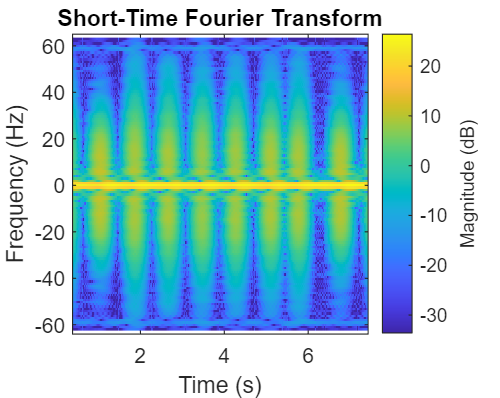

Fs=126;
win = hamming(100,'periodic');
stft(ECGData.Data(1,1:1000),Fs,'Window',win,'OverlapLength',98,'FFTLength',128);

xlim([0.38 7.43])
ylim([-64 65])

### **2.2 Create the spectrograms as RGB images  **

To be compatible with the pre-trained Networks architecture, we create the spectrograms as RGB images using the helper function `helperCreateRGBfromSTF`. Each RGB image is an array with the dimensions 224x224x3.

helperCreateRGBfromSTF(ECGData,parentDir2,dataDir2)

### **2.3 Divide Spectrograms Images into Training and Validation Data**

Load the spectrogram images as an image datastore. The `imageDatastore` function automatically labels the images based on folder names and stores the data as an ImageDatastore object.

allImages2 = imageDatastore(fullfile(parentDir2,dataDir2),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

Randomly we divided the images into two groups, one for training and the other for validation. 

Set 80% of the images for training and the rest for validation. For the purpose of reproducibility, we set the random seed to the default value.

rng default
[imgsTrain2,imgsValidation2] = splitEachLabel(allImages2,0.8,'randomized');
disp(['Number of training images(Spectrograms): ',num2str(numel(imgsTrain2.Files))]);

Number of training images(Spectrograms): 130


disp(['Number of validation images(Spectrograms): ',num2str(numel(imgsValidation2.Files))]);

Number of validation images(Spectrograms): 32


### **2.4 Design of the Convolutional Neural Networks (CNN)**

For designing the CNNs, the following pretrained networks shall be used: GoogLeNet, SqueezeNet and AlexNet.We then adopt the networks to the ECG classification. We use the same modified networks used for Continuous Wavelet Transformation (CWT) to avoid repetition and to ease the work. This avoids the designing of the networks as they are done already.

### 2.5 Training the Networks

We train our three networks in this step.

#### (2.5.1) GoogleNet

**(a) Decide on the training parameters and train the network**

Using trial and error method, we find the best value for the number of epochs and batch-size to generate a good model without overfitting and underfitting. We found the optimum `MaxEpochs` value to be 20 and `MiniBatchSize` to be 11. We set the `InitialLearnRate` to 0.0001.

ilr_gn = 0.0001; %Initial learning rate
miniBatchSize_gn = 11;
maxEpochs_gn = 20;

options1 = trainingOptions('sgdm',...
    'MiniBatchSize',miniBatchSize_gn,...
    'MaxEpochs',maxEpochs_gn,...
    'InitialLearnRate',ilr_gn,...
    'ValidationData',imgsValidation2,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Training the Network

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       18.18% |       53.12% |       4.0634 |       1.4256 |      1.0000e-04 |
|       1 |          10 |       00:00:30 |       27.27% |       53.12% |       1.6751 |       1.0015 |      1.0000e-04 |
|       2 |          20 |       00:00:57 |       63.64% |       53.12% |       0.9712 |       0.8631 |      1.0000e-04 |
|       3 |          30 |       00:01:19 |       81.82% |       68.75% |       0.4187 |       0.7569 |      1.0000

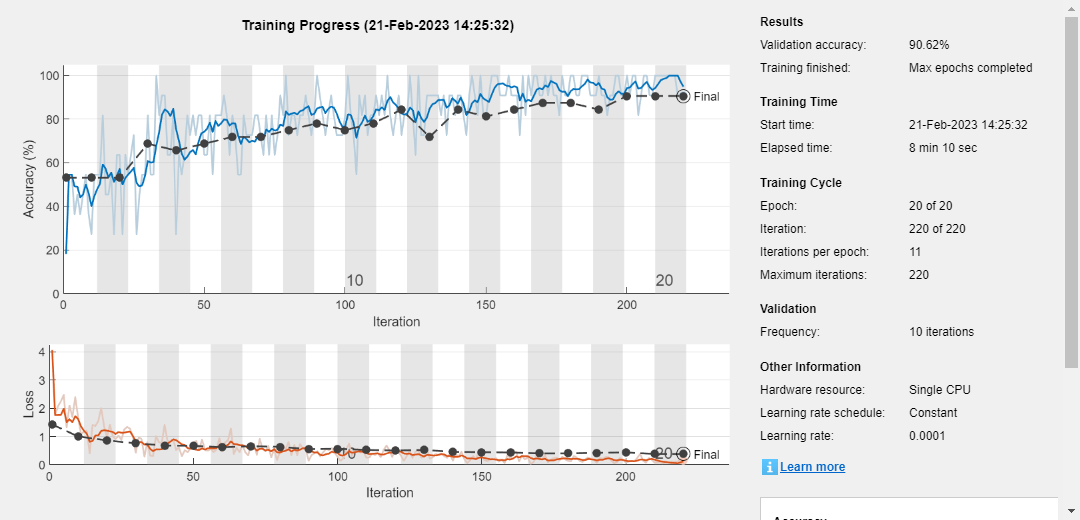

trainedGN2 = trainNetwork(imgsTrain2,lgraphGN,options1);

trainedGN2.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


**(b) Evaluating the training results**

**GoogLeNet Accuracy**

Evaluate the network using the validation data. 

Since there is an insufficient amount of data to divide into training, validation, and testing, we treat the computed validation accuracy as the network accuracy.

[YPred1,~] = classify(trainedGN2,imgsValidation2);
accuracy = mean(YPred1==imgsValidation2.Labels);
disp(['GoogLeNet Accuracy: ',num2str(100*accuracy),'%'])

GoogLeNet Accuracy: 90.625%


Display four sample validation images with their predicted labels.

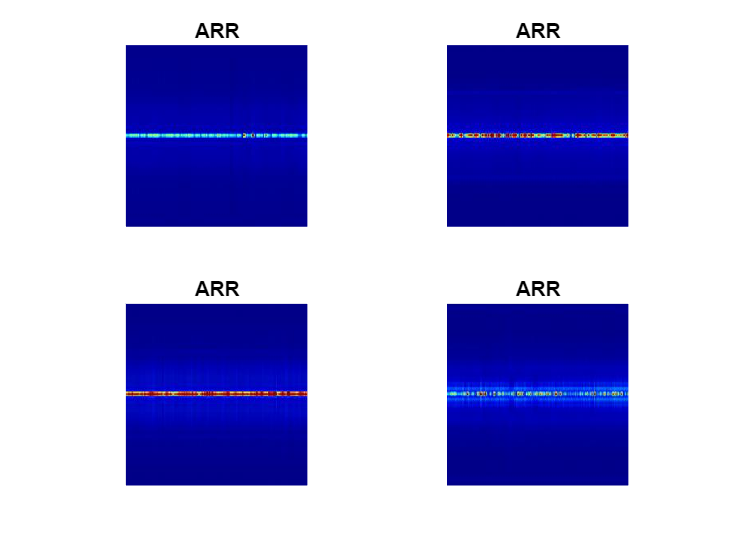

%idx = randperm(numel(imgsValidation.Files),4);
idx = [11,12,13,9];
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsValidation2,idx(i));
    imshow(I)
    label = YPred1(idx(i));
    title(string(label));
end

#### **(2.5.2) SqueezeNet**

**(a) Prepare RGB Data for SqueezeNet**

For the purpose of creating augmented image datastores that accordingly resize the existing RGB images for the SqueezeNet architecture.

augimgsTrain2 = augmentedImageDatastore([227 227],imgsTrain2);
augimgsValidation2 = augmentedImageDatastore([227 227],imgsValidation2);

**(b) Decide on the training parameters and train the network**

Using trial and error method, we find the best value for the number of epochs and batch-size to generate a good model without overfitting and underfitting. We found the optimum `MaxEpochs` value to be 17 and `MiniBatchSize` to be 10. We set the `InitialLearnRate` to 0.0001.

ilr_sn = 0.0001; %Initial learning rate
miniBatchSize_sn = 10;
maxEpochs_sn = 17;
valFreq = floor(numel(augimgsTrain2.Files)/miniBatchSize_sn);

valFreq = 13


options2 = trainingOptions('sgdm',...
    'MiniBatchSize',miniBatchSize_sn,...
    'MaxEpochs',maxEpochs_sn,...
    'InitialLearnRate',ilr_sn,...
    'ValidationData',augimgsValidation2,...
    'ValidationFrequency',valFreq,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

rng default

Training the Network

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       20.00% |       21.88% |       3.0063 |       2.3406 |      1.0000e-04 |
|       1 |          13 |       00:00:15 |       60.00% |       59.38% |       0.9902 |       0.9606 |      1.0000e-04 |
|       2 |          26 |       00:00:29 |       80.00% |       59.38% |       0.9603 |       1.0245 |      1.0000e-04 |
|       3 |          39 |       00:00:41 |       70.00% |       71.88% |       0.8273 |       0.8594 |      1.0000

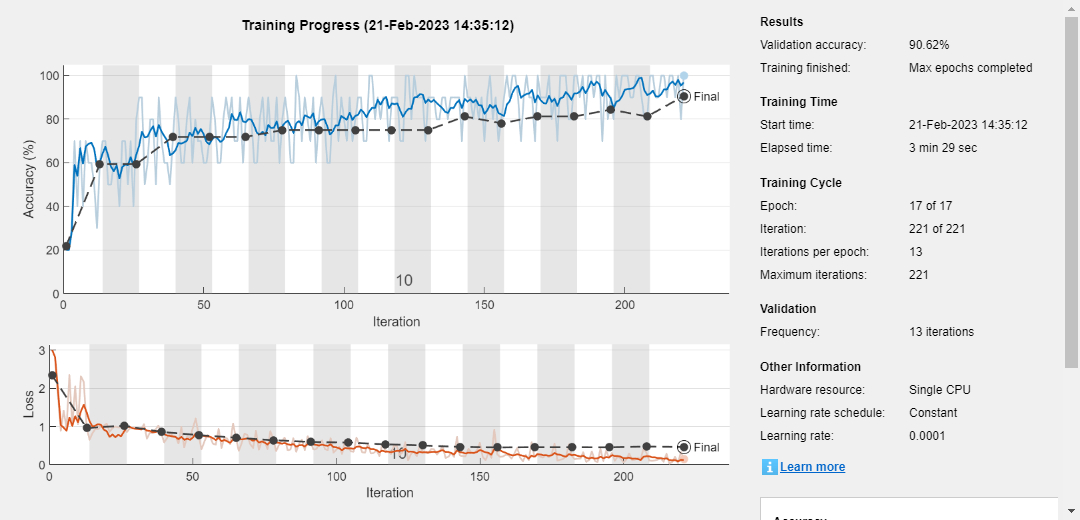

trainedSN2 = trainNetwork(augimgsTrain2,lgraphSqz,options2);

trainedSN2.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


**(c) Evaluating the training results**

**SqueezeNet Accuracy**

Evaluate the network using the validation data. 

[YPred2,~] = classify(trainedSN2,augimgsValidation2);
accuracy = mean(YPred2==imgsValidation2.Labels);
disp(['SqueezeNet Accuracy: ',num2str(100*accuracy),'%'])

SqueezeNet Accuracy: 90.625%


Display four sample validation images with their predicted labels

idx = [11,12,13,9];
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsValidation2,idx(i));
    imshow(I)
    label = YPred2(idx(i));
    title(string(label));
end

#### (2.5.3) AlexNet

**(a) Prepare RGB Data for AlexNet**

For the purpose of creating augmented image datastores that accordingly resize the existing RGB images for the AlexNet architecture.

augimgsTrain2 = augmentedImageDatastore([227 227],imgsTrain2);
augimgsValidation2 = augmentedImageDatastore([227 227],imgsValidation2);

**(b) Decide on the training parameters and train the network**

Using trial and error method, we find the best value for the number of epochs and batch-size to generate a good model without overfitting and underfitting. We found the optimum `MaxEpochs` value to be 17 and `MiniBatchSize` to be 11. We set the `InitialLearnRate` to 0.0001.

ilr_an = 0.0001; %Initial learning rate
miniBatchSize_an = 11;
maxEpochs_an = 17;
valFreq = floor(numel(augimgsTrain2.Files)/miniBatchSize_an)

valFreq = 11



options3 = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize_an, ...
    'MaxEpochs',maxEpochs_an, ...
    'InitialLearnRate',ilr_an, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimgsValidation2, ...
    'ValidationFrequency',valFreq, ...
    'Verbose',1, ...
    'Plots','training-progress');
rng default

Training the Network

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       27.27% |       40.62% |       2.3308 |       1.3835 |      1.0000e-04 |
|       1 |          11 |       00:00:15 |       63.64% |       43.75% |       1.0272 |       1.0869 |      1.0000e-04 |
|       2 |          22 |       00:00:27 |       81.82% |       75.00% |       0.5573 |       0.5633 |      1.0000e-04 |
|       3 |          33 |       00:00:39 |       90.91% |       71.88% |       0.2280 |   

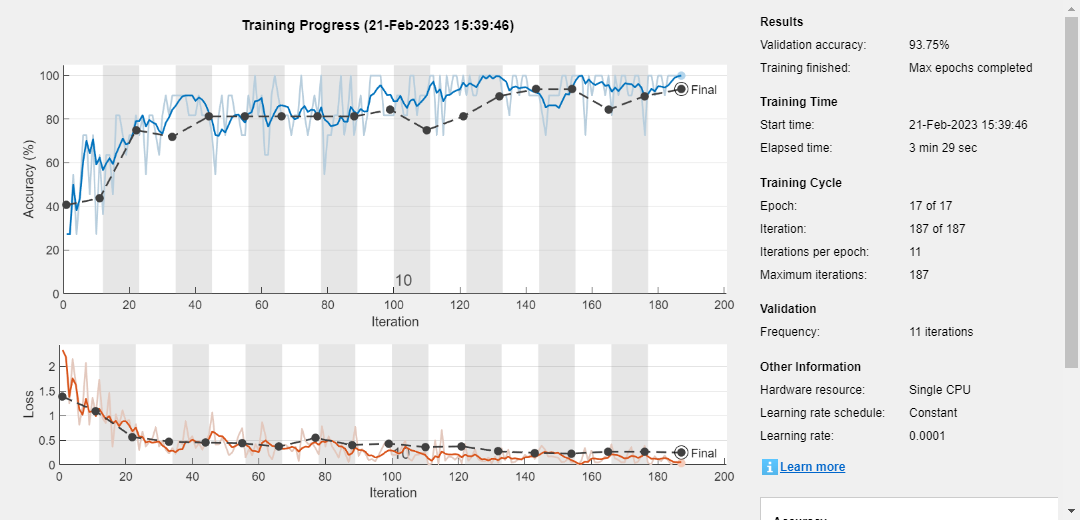

netTransfer2 = trainNetwork(augimgsTrain2,lgraphAlx,options3);

netTransfer2.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


**(c) Evaluating the training results**

**AlexNet Accuracy**

Evaluate the network using the validation data. 

[YPred3,~] = classify(netTransfer2,augimgsValidation2);
accuracy = mean(YPred3==imgsValidation2.Labels);
disp(['ALexNet Accuracy: ',num2str(100*accuracy),'%'])

ALexNet Accuracy: 93.75%


Display four sample validation images with their predicted labels

idx = [11,12,13,9];
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsValidation2,idx(i));
    imshow(I)
    label = YPred3(idx(i));
    title(string(label));
end

### 2.6 Testing and validating the Networks - Confusion Charts

We compare the results and the reliabilty of the different Time and Frequency Representations of the three different Networks.

#### Confusion Charts - Comparison

**(2.6.1) GoogleNet Confusion Chart**

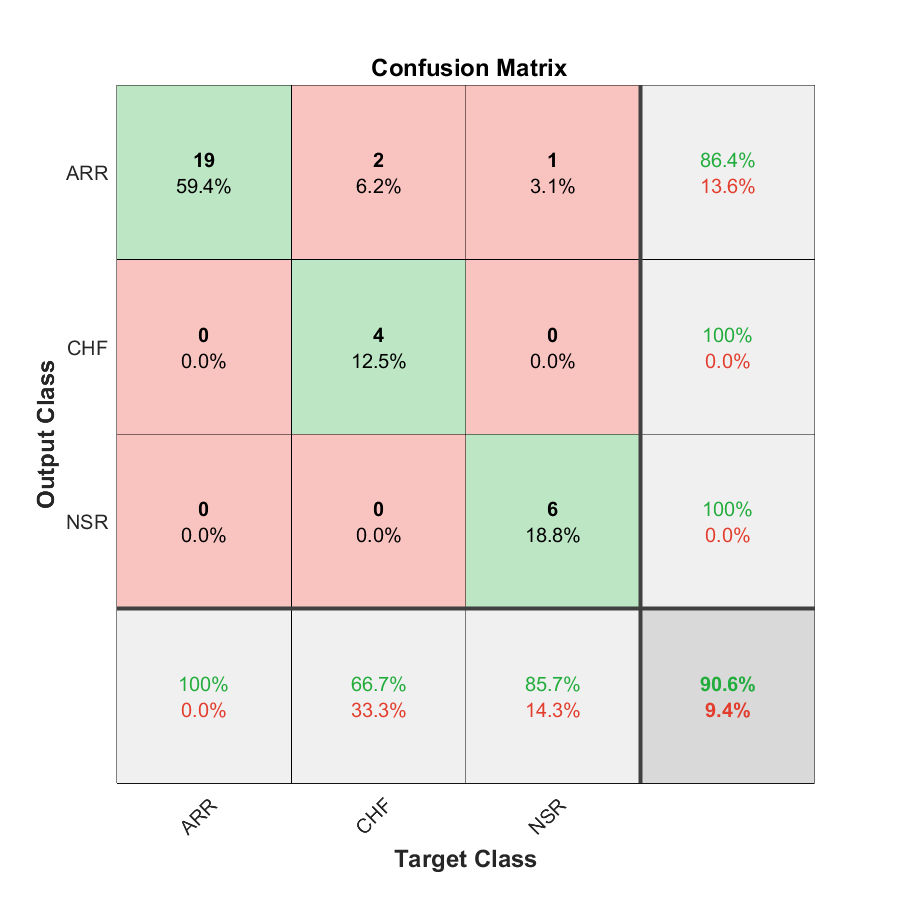

plotconfusion(imgsValidation2.Labels,YPred1)

In CHF, it is shown that out of 6 testing images, 4 were accurately classified, 2 were misclassified as ARR. In addition to that, NSR images have got 6 accurate predictions while only one image is misclassified under ARR category. On the other hand, all 19 ARR images have got accurate predictions.

**(2.6.2) SqueezNet Confusion Chart**

plotconfusion(imgsValidation2.Labels,YPred2)

Upon analysing the confusion chart obtained for SqueezeNet model, we can see that in ARR, out of 19 testing images, all are correctly classified. However, for CHF 4 images were classified correctly and 2 images were misclassified under ARR, and for NSR, 6 images have identified correctly but a single image was predicted as ARR image.

**(2.6.3) AlexNet Confusion Chart**

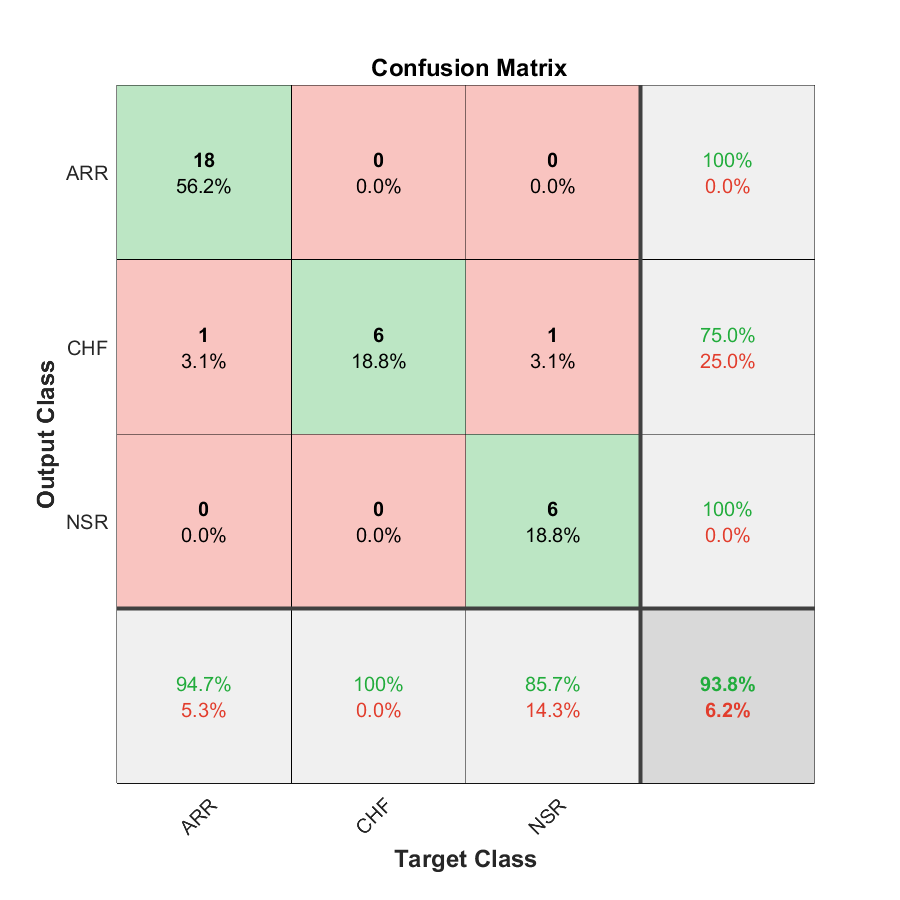

plotconfusion(imgsValidation2.Labels,YPred3)

While analysing the confusion chart obtained for AlexNet model, we can see that in ARR, out of 19 testing images, 18 images are correctly classified, meanwhile one image is misclassified as CHF. However, for CHF all 6 images were classified correctly, but in the case of NSR, 6 images have identified correctly and a remaining one image was predicted as ARR image.

### 2.7 Application of the Networks to the given ECG Signal

First step is to transform the given signal wavelet to an RGB Image:

ecg =load('ecg.mat');
y=ecg.data

Unrecognized field name "data".

Fs=ecg.fs

folderpath = strcat('given_signal'); %put your path here
win = hamming(100,'periodic');
s=stft(y,Fs,'Window',win,'OverlapLength',98,'FFTLength',128);
smag=abs(s);
sphs=angle(s);

im = ind2rgb(im2uint8(rescale(smag)),jet(128));
imwrite(imresize(im,[224 224]),fullfile(folderpath,'given_signal_Spectogram.jpg'));

**Reading the given signal wavelet (Spectrogram) image**

I = imread('C:\Users\abhir\Dropbox\My PC (LAPTOP-HNUHSA8N)\Desktop\DSP\given_signal\given_signal_Spectogram.jpg');
figure
imshow(I)
title('Given Signal (Short Time Fourier Transform)')

#### (2.7.1) Prediction using GoogleNet

First we need to check the Image size because the GoogleNet model requires the image size to be the same as the input size of the network. If not, we need to resize the transformed image to the input image size of the GoogLeNet Network.

sizeGN = net1.Layers(1).InputSize; %Input image size of the GoogLeNet Network
Image_size = size(I); %Size of the given image
sizeGN
Image_size

Prediction of the given signal by using GoogleNet Network.

%I = imresize(I,sizGN(1:2));
labelGN2 = classify(trainedGN,I)
figure
imshow(I)
title(labelGN2)

#### (2.7.2) Prediction using SqueezeNet

Resizing the given transformed image to the input size of the SqueezeNet network.

sizeSQ = net2.Layers(1).InputSize; %Input image size of the SqueezeNet Network
I2 = imresize(I,sizeSQ(1:2));
Image_size2 = size(I2); %Size of the given image
sizeSQ
Image_size2

Prediction of the given signal by using SqueezeNet Network.

labelSQ2= classify(trainedSN,I2)
figure
imshow(I2)
title(labelSQ2)

#### (2.7.3) Prediction using AlexNet

Resize the given image to the input size of the AlexNet network.

sizeAN = net3.Layers(1).InputSize; %Input image size of the AlexNet Network
I3 = imresize(I,sizeAN(1:2));
Image_size3 = size(I3); %Size of the given image
sizeAN
Image_size3

Prediction of the given signal by using AlexNet Network.

labelAL= classify(netTransfer2,I3)
figure
imshow(I3)
title(labelAL)

## Conclusion

In this project, we have implemented two types of time-frequency representation, namely Continuous Wavelet Transformation and Short Time Fourier Transformation. The objective was to train three pre-trained CNNs (GoogLeNet, SqueezeNet, and AlexNet) to classify three types of ECG signals, namely ARR, CHF, and NSR, by creating RGB images of Scalograms and Spectrograms. The results indicate that the CNNs trained with the Scalograms outperformed those trained with Spectrograms, achieving an average accuracy of 96.88 % across all CNNs.

Upon examining the results of all the prediction outcomes made by the CNNs, it was observed that the NSR ECG signal type was predicted most frequently. Consequently, it can be deduced that the given ECG signal belongs to the NSR type.

### **Supporting Functions**

**1-helperCreateECGDataDirectories** creates a data directory inside a parent directory, then creates three subdirectories inside the data directory. The subdirectories are named after each class of ECG signal found in `ECGData`.

function helperCreateECGDirectories(ECGData,parentFolder,dataFolder)


rootFolder = parentFolder;
localFolder = dataFolder;
mkdir(fullfile(rootFolder,localFolder))

folderLabels = unique(ECGData.Labels);
for i = 1:numel(folderLabels)
    mkdir(fullfile(rootFolder,localFolder,char(folderLabels(i))));
end
end

**2-helperPlotReps** plots the first thousand samples of a representative of each class of ECG signal found in `ECGData`.

function helperPlotReps(ECGData)


folderLabels = unique(ECGData.Labels);

for k=1:3
    ecgType = folderLabels{k};
    ind = find(ismember(ECGData.Labels,ecgType));
    subplot(3,1,k)
    plot(ECGData.Data(ind(1),1:1000));
    grid on
    title(ecgType)
end
end

**3-helperCreateRGBfromTF** uses [`cwtfilterbank`](https://de.mathworks.com/help/wavelet/ref/cwtfilterbank.html) to obtain the continuous wavelet transform of the ECG signals and generates the scalograms from the wavelet coefficients. The helper function resizes the scalograms and writes them to disk as jpeg images.

function helperCreateRGBfromTF(ECGData,parentFolder,childFolder)


imageRoot = fullfile(parentFolder,childFolder);

data = ECGData.Data;
labels = ECGData.Labels;

[~,signalLength] = size(data);

fb = cwtfilterbank('SignalLength',signalLength,'VoicesPerOctave',12);
r = size(data,1);

for ii = 1:r
    cfs = abs(fb.wt(data(ii,:)));
    im = ind2rgb(im2uint8(rescale(cfs)),jet(128));
    imgLoc = fullfile(imageRoot,char(labels(ii)));
    imFileName = strcat(char(labels(ii)),'_',num2str(ii),'.jpg');
    imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName));
end
end

**4-helperCreateRGBfromSTF**

function helperCreateRGBfromSTF(ECGData,parentFolder,childFolder)
imageRoot = fullfile(parentFolder,childFolder);
data = ECGData.Data;
labels = ECGData.Labels;

Fs=126;

win = hamming(100,'periodic');


r = size(data,1);

for ii = 1:r
    

    s=stft((data(ii,:)),Fs,'Window',win,'OverlapLength',98,'FFTLength',128);
    %s=stft((data(ii,:)),Fs,'Window',wind,'OverlapLength',olen,'FFTLength',nfft);
    smag=abs(s);
    sphs=angle(s);
    im = ind2rgb(im2uint8(rescale(smag)),jet(128));
    imgLoc = fullfile(imageRoot,char(labels(ii)));
    imFileName = strcat(char(labels(ii)),'_',num2str(ii),'.jpg');
    imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName))
end
end